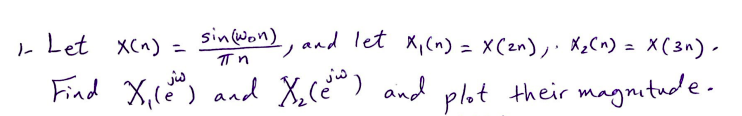

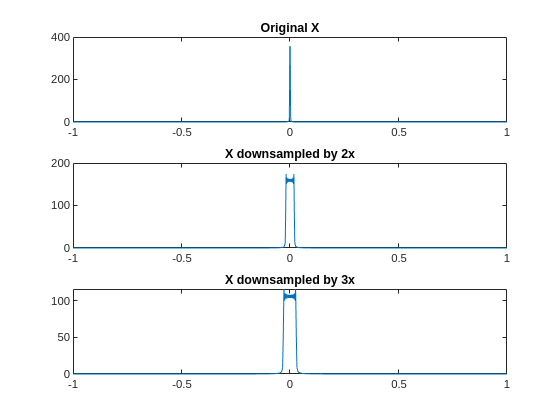

w = 1;
T = 0.001;
n = -2:T:2;
n_1 = -10:2*T:10;
n_2 = -10:3*T:10;

x = (w/pi)*sinc(w*n);
x_1 = (w/pi)*sinc(w*n_1);
x_2 = (w/pi)*sinc(w*n_2);

X = fft(x);
X_1 = fft(x_1);
X_2 = fft(x_2);

subplot(3,1,1)
plot(n,abs(fftshift(X)))
title("Original X")
xlim([-1, 1])

subplot(3,1,2)
plot(n_1,abs(fftshift(X_1)))
title("X downsampled by 2x")
xlim([-1,1])

subplot(3,1,3)
plot(n_2,abs(fftshift(X_2)))
title("X downsampled by 3x")
xlim([-1,1])

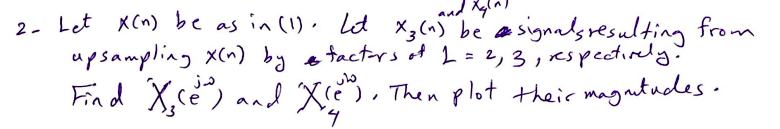

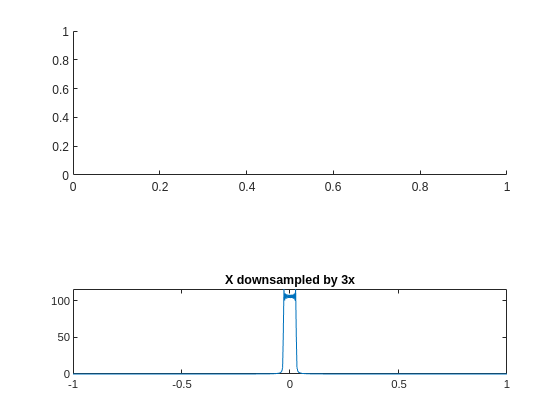

x_3 = DSP_funcs.resampleSINC(x, 2);
x_4 = DSP_funcs.resampleSINC(x, 3);

n_3 = -10:T/2:10 + T/2;
n_4 = -10:T/3:10 + 2*T/3;

X_3 = fft(x_3);
X_4 = fft(x_4);

subplot(2,1,1)

plot(n_3, abs(fftshift(X_3)));

Error using plot
Vectors must be the same length.

title("X Upsampled by a factor of 2")
xlim([-1,1])

subplot(2,1,2)
plot(n_4, abs(fftshift(X_4)))
title("X Upsampled by a factor of 3")
xlim([-1,1])
